## 主函数

%% 准备数据

clc;clear;close all;
load('data2.mat') %DAB数据

%设置训练数据和测试数据

m = size(input, 1);  % Get the number of samples

% 定义划分比例

train_ratio = 0.8; % 训练集比例为70%
test_ratio = 0.2;  % 测试集比例为10%

% 计算用于训练、验证、测试的样本数量

train_num=round(train_ratio*m); %自变量 
test_num = m - train_num;

% 创建随机排列的索引

shuffled_indices = randperm(m);

% 使用随机排列的索引来获取打乱后的数据

shuffled_input = input(shuffled_indices, :);
shuffled_output = output(shuffled_indices, :);

`% 划分数据为训练集、验证集和测试集`

x_train_data = shuffled_input(1:train_num, :);
y_train_data = shuffled_output(1:train_num, :);
x_test_data = shuffled_input(train_num+1:end, :);
y_test_data = shuffled_output(train_num+1:end, :);

% 标准化，进行最小-最大归一化

% 如果需要，进行最大最小值（Min-Max）归一化
% 注意：这里将x_train_data和y_train_data的归一化参数应用到验证集和测试集
x_train_min = min(x_train_data, [], 1);
x_train_max = max(x_train_data, [], 1);

y_train_min = min(y_train_data, [], 1);
y_train_max = max(y_train_data, [], 1);


% 最小-最大归一化 x_train_data 和 y_train_data

x_train_data_n = (x_train_data - x_train_min) ./ (x_train_max - x_train_min);
y_train_data_n = (y_train_data - y_train_min) ./ (y_train_max - y_train_min);
x_test_data_n = (x_test_data - x_train_min) ./ (x_train_max - x_train_min);

%转置使其符合网络要求newff

x_train_data_n = x_train_data_n';
y_train_data_n = y_train_data_n';
x_test_data_n = x_test_data_n'; %测试输出不需要归一化
%y_test_data = y_test_data';

%% 初始化参数

EMS_all1=[];
EMS_all2=[];
EMS_all3=[];
EMS_all4=[];
EMS_all5=[];
TIME=[];
num_iter_all=5;  %10
for NN=1:num_iter_all
input_num=size(x_train_data,2); %输入特征个数
hidden_num=16;   %隐藏层神经元个数
output_num=size(y_train_data,2); %输出特征个数

% 遗传算法参数初始化

iter_num=30;  %   200                    %总体进化迭代次数
group_num=30;                      %种群大小50
cross_pro=0.82;                       %交叉概率
mutation_pro=0.01;                  %变异概率，相对来说比较小
%这个优化的主要思想就是优化网络参数的初始选择，初始选择对于效果好坏是有较大影响的
num_all=input_num*hidden_num+hidden_num+hidden_num*output_num+output_num; %编码长度
%网络总参数，只含一层隐藏层,input_num*hidden=w,+hidden_num=b,hidden_num*output_num=w,output_num=b
lenchrom=ones(1,num_all);  %染色体总长度
limit=[-2*ones(num_all,1) 2*ones(num_all,1)];    %初始参数取值范围
t1=clock;

%% 初始化种群（初始化染色体长度）

input_data=x_train_data_n;
output_data=y_train_data_n;
for i=1:group_num
    initial=rand(1,length(lenchrom));  %产生0-1的随机数
    initial_chrom(i,:)=limit(:,1)'+(limit(:,2)-limit(:,1))'.*initial; %变成染色体的形式，一行为一条染色体
    fitness_value=fitness1(initial_chrom(i,:),input_num,hidden_num,output_num,input_data,output_data);
    fitness_group(i)=fitness_value;
end
[bestfitness,bestindex]=min(fitness_group);
bestchrom=initial_chrom(bestindex,:);  %最好的染色体
avgfitness=sum(fitness_group)/group_num; %染色体的平均适应度                              
trace=[avgfitness bestfitness]; % 记录每一代进化中最好的适应度和平均适应度

%% 迭代过程，迭代求解最佳初始阀值和权值

% 进化开始

input_chrom=initial_chrom;
% iter_num=1;
 for num=1:iter_num
    % 选择  
     [new_chrom,new_fitness]=select(input_chrom,fitness_group,group_num);   %把表现好的挑出来，还是和种群数量一样
%    avgfitness=sum(new_fitness)/group_num; 
    %交叉  
     new_chrom=Cross(cross_pro,lenchrom,new_chrom,group_num,limit);
    % 变异  
     new_chrom=Mutation(mutation_pro,lenchrom,new_chrom,group_num,num,iter_num,limit);     
    % 计算适应度   
    for j=1:group_num  
        sgroup=new_chrom(j,:); %个体 
        new_fitness(j)=fitness1(sgroup,input_num,hidden_num,output_num,input_data,output_data);     
    end  
    %找到最小和最大适应度的染色体及它们在种群中的位置
    [newbestfitness,newbestindex]=min(new_fitness);
    [worestfitness,worestindex]=max(new_fitness);
    

%  最优个体更新，代替上一次进化中最好的染色体

    if  bestfitness>newbestfitness
        bestfitness=newbestfitness;
        bestchrom=new_chrom(newbestindex,:);
    end
    new_chrom(worestindex,:)=bestchrom; %用最好的代替最差的，精英策略
    new_fitness(worestindex)=bestfitness;
    avgfitness=sum(new_fitness)/group_num;
    trace=[trace;avgfitness bestfitness]; %记录每一代进化中最好的适应度和平均适应度
 end
%%
figure(1)
[r ,~]=size(trace);
plot([1:r]',trace(:,2),'b--');
title(['适应度曲线  ' '终止代数＝' num2str(iter_num)]);
xlabel('进化代数');ylabel('适应度');
legend('最佳适应度');
 
%% 把最优初始阀值权值赋予网络预测
% %用遗传算法优化的BP网络进行值预测
net=newff(x_train_data_n,y_train_data_n,hidden_num,{'tansig','purelin'});
w1=bestchrom(1:input_num*hidden_num);   %输入和隐藏层之间的权重参数
B1=bestchrom(input_num*hidden_num+1:input_num*hidden_num+hidden_num); %隐藏层神经元的偏置
w2=bestchrom(input_num*hidden_num+hidden_num+1:input_num*hidden_num+...
    hidden_num+hidden_num*output_num);  %隐藏层和输出层之间的偏置
B2=bestchrom(input_num*hidden_num+hidden_num+hidden_num*output_num+1:input_num*hidden_num+...
    hidden_num+hidden_num*output_num+output_num); %输出层神经元的偏置
%网络权值赋值
net.iw{1,1}=reshape(w1,hidden_num,input_num);
net.lw{2,1}=reshape(w2,output_num,hidden_num);
net.b{1}=reshape(B1,hidden_num,1);
net.b{2}=reshape(B2,output_num,1);

%网络经过GA优化之后

net.trainParam.epochs=100;          %最大迭代次数200
net.trainParam.lr=0.1;                        %学习率
net.trainParam.goal=0.00001;        % 训练目标（goal），当训练误差达到该目标时，停止训练
[net,~]=train(net,x_train_data_n,y_train_data_n); 

%将输入数据归一化
%x_test_regular = mapminmax('apply',x_test_data,x_train_maxmin);
%放入到网络输出数据
y_test_pred_n=sim(net,x_test_data_n);
%将得到的数据反归一化得到预测数据
%GA_BP_predict=mapminmax('reverse',y_test_regular,y_train_maxmin);
y_test_pred = y_test_pred_n' .* (y_train_max - y_train_min) + y_train_min; %MAPE
MARE=sum(abs(y_test_pred-y_test_data)./(y_test_data))/length(y_test_data).*100; 

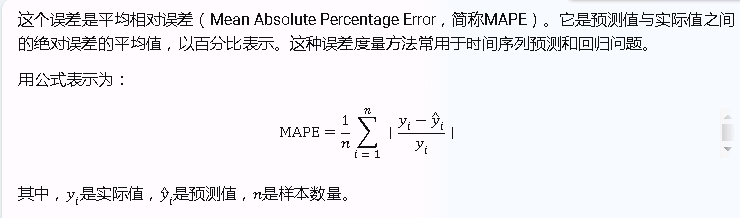

RMSE=sqrt(sum((y_test_pred-y_test_data).^2)/length(y_test_data));

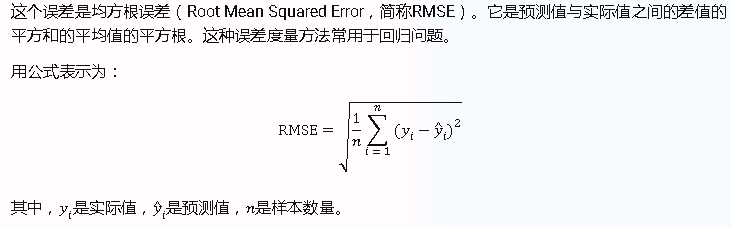

y_test_pred_mean = mean(y_test_pred);
y_test_data_mean = mean(y_test_data);
% 计算公式中的分子和分母
numerator = sum((y_test_pred - y_test_pred_mean) .* (y_test_data - y_test_data_mean));
denominator = sqrt(sum((y_test_pred - y_test_pred_mean).^2) .* sum((y_test_data - y_test_data_mean).^2));
R_value = numerator ./ denominator; %相关性的值
R_E = (y_test_pred-y_test_data)./y_test_data.*100; %相对误差
A_E = abs(y_test_pred-y_test_data); %绝对误差
t2=clock;
Time_all=etime(t2,t1);
EMS_all1=[EMS_all1;MARE];
EMS_all2=[EMS_all2;RMSE];
EMS_all3=[EMS_all3;R_value];
EMS_all4{NN} = R_E;
EMS_all5{NN} = A_E;
TIME=[TIME;Time_all];
end
average_MARE = mean(EMS_all1, 1); 
average_RMSE = mean(EMS_all2, 1);
average_R_value = mean(EMS_all3, 1);
average_R_E = mean(cat(num_iter_all, EMS_all4{:}), num_iter_all);
average_A_E = mean(cat(num_iter_all, EMS_all5{:}), num_iter_all);
average_Time_all = mean(TIME, 1);
%%
figure(2)
% EMS_all=[0.149326909497551,0.142964890977319,0.145465721759172,0.144173052409406,0.155684223205026,0.142331921077465,0.144810383902860,0.144137917725977,0.149229175194219,0.143762158676095];
plot(EMS_all1,'LineWidth',2)
xlabel('实验次数')
ylabel('误差')
hold on
figure(3)
color=[111,168,86;128,199,252;112,138,248;184,84,246]/255;
plot(y_test_data,'Color',color(2,:),'LineWidth',1)
hold on
plot(y_test_pred,'*','Color',color(1,:))
hold on
plot(average_R_E,'*','Color',color(1,:))
hold on
legend('真实数据','预测数据')
disp('相对误差为：')
disp(RMSE)
titlestr=['BP神经网络','   误差为：',num2str(min(RMSE))];
title(titlestr)
hold on
% 循环遍历每个特征
for feature_index = 1:output_num
    % 选择当前特征的数据
    feature_data = y_test_data(:, feature_index);
    feature_pred = y_test_pred(:, feature_index);
    feature_R_E = average_R_E(:, feature_index);
    % 创建一个新的图形窗口
    figure;
    
    % 绘制当前特征的数据
    plot(feature_data, 'LineWidth',1.5,'Color',[1.00,0.00,0.00]); % 这里使用了 -o 标记来表示点
    hold on
    plot(feature_pred, ':','linewidth',1.5,'Color',[0.39 0.83 0.07]);
    hold on
    plot(feature_R_E, 'LineWidth',0.5,'Color',[0.0745098039215686 0.623529411764706 1]);
    % 添加标题和标签
    title(['data ' , ' pred',' Error']);
    xlabel('Sample Index');
    ylabel('Error Value');
end


% 计算输入与输出的相关性并绘制热力图
corrcoefMatrix = corrcoef([inputs; outputs]);
imagesc(corrcoefMatrix);
colorbar;
title('输入与输出相关性热力图');
figure(3)
